# Homework 6

**Name:** YOUR NAME HERE

**Last modified: **June 29, 2022

clear, clc

## Problem #1 - Eigenvalues

**SETUP FOR PROBLEM**

A = [19 -12
     36 -23];

**a) Eigenvalues "by hand"**


$$\begin{array}{l}
\left\lbrack \lambda I-A\right\rbrack =0\\
A=\left\lbrack \begin{array}{cc}
19 & -12\\
36 & -23
\end{array}\right\rbrack \\
A-\lambda I=0\\
\left\lbrack \begin{array}{cc}
19-\lambda  & -12\\
36 & -23-\lambda 
\end{array}\right\rbrack =0\\
\left(19-\lambda \right)\left(-23-\lambda \right)-36\left(-12\right)=0\\
\lambda^2 +4\lambda -437+432=0\\
\lambda^2 +4\lambda -5=0\\
\left(\lambda +5\right)\left(\lambda -1\right)=0\\
\lambda =-5,1
\end{array}$$


**b) Eigenvectors "by hand"**


$$\begin{array}{l}
\left\lbrack A-\lambda_i I\right\rbrack V_i =0\\
V_i =\left\lbrack \begin{array}{c}
v_i^1 \\
v_i^2 
\end{array}\right\rbrack \\
\lambda =-5\\
\left\lbrace \left\lbrack \begin{array}{cc}
19 & -12\\
36 & -23
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
-5 & 0\\
0 & -5
\end{array}\right\rbrack \right\rbrace V_{-5} =0\\
\left\lbrack \begin{array}{cc}
24 & -12\\
36 & -18
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_{-5}^1 \\
v_{-5}^2 
\end{array}\right\rbrack =0\\
24v_{-5}^1 -12v_{-5}^2 =0\\
36v_{-5}^1 -18v_{-5}^2 =0\\
V_{-5} =\left\lbrack \begin{array}{c}
1\\
2
\end{array}\right\rbrack \\
\\
\lambda =1\\
\left\lbrace \left\lbrack \begin{array}{cc}
19 & -12\\
36 & -23
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \right\rbrace V_1 =0\\
\left\lbrack \begin{array}{cc}
18 & -12\\
36 & -24
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_1^1 \\
v_1^2 
\end{array}\right\rbrack =0\\
18v_1^1 -12v_1^2 =0\\
36v_1^1 -24v_1^2 =0\\
V_1 =\left\lbrack \begin{array}{c}
2\\
3
\end{array}\right\rbrack 
\end{array}$$


**c) Calculate eigenvalues and eigenvectors using eig**

[A,B] = eig(A)

A =     0.5547    0.4472
    0.8321    0.8944


B =      1     0
     0    -5


**d) Show eigenvalues and eigenvalues from parts a-c are same**

fprintf("The Eigenvectors from MATLAB are [%.4f; %.4f] and [%.4f; %.4f]", A(1,1), A(2,1), A(1,2), A(2,2))

The Eigenvectors from MATLAB are [0.5547; 0.8321] and [0.4472; 0.8944]

Eig_hand = [2 1
            3 2];
eig_1 = sqrt(Eig_hand(1,1)^2 + Eig_hand(2,1)^2);
eig_2 = sqrt(Eig_hand(1,2)^2 + Eig_hand(2,2)^2);
Eig_hand_norm = [Eig_hand(:,1)/eig_1 Eig_hand(:,2)/eig_2];
fprintf("The Eigenvectors by hand are [%.4f; %.4f] and [%.4f; %.4f]", Eig_hand_norm(1,1), Eig_hand_norm(2,1), Eig_hand_norm(1,2), Eig_hand_norm(2,2))

The Eigenvectors by hand are [0.5547; 0.8321] and [0.4472; 0.8944]

## Problem #2 - Differentiation

**SETUP FOR PROBLEM**

f = @(t) 4.8*exp(4*t).*sin(-9*t);

**a) Plot the function**

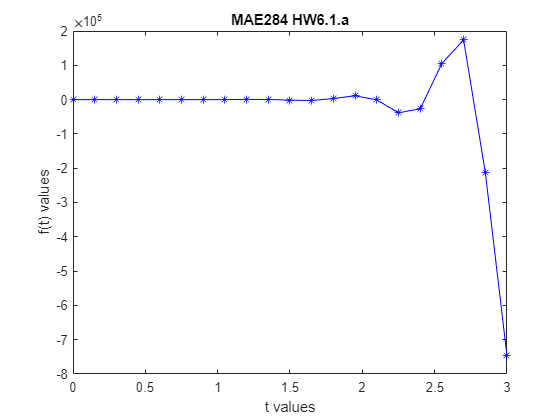

t = 0:.15:3;
y = f(t);
figure()
plot(t, y,"-b*")
title("MAE284 HW6.1.a")
xlabel("t values")
ylabel("f(t) values")

**b) Calculate the derivative analytically using symbolic toolbox**

syms t
F(t) = 4.8*exp(4*t)*sin(-9*t);
dF = diff(F)

$$dF(t) = -\frac{216\,\cos\left(9\,t\right)\,{\mathrm{e}}^{4\,t}}{5}-\frac{96\,\sin\left(9\,t\right)\,{\mathrm{e}}^{4\,t}}{5}$$

**c) Calculate using diff**

t = 0:.15:3;
y_diff = diff(y)./diff(t);
t_diff = (t(1:end-1)+t(2:end))/2;

**d) Calculate using gradient**

y_grad = gradient(y,t);

**e) Plot the derivatives from b-d**

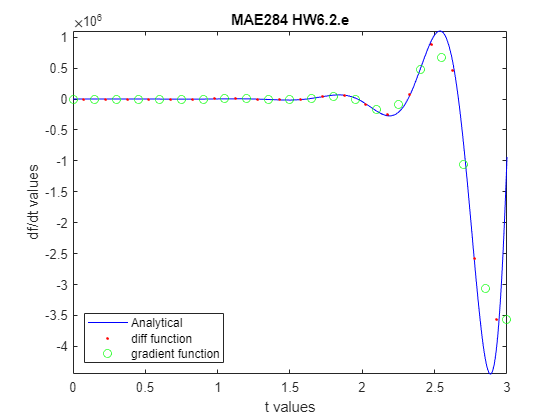

figure()
fplot(dF, [0 3], "-b")
hold on
plot(t_diff, y_diff, "r.", t, y_grad,"go")
title("MAE284 HW6.2.e")
xlabel("t values")
ylabel("df/dt values")
legend("Analytical", "diff function", "gradient function", "location", "southwest")
hold off

## Problem #3 - Boundary value problem #1

**SETUP FOR PROBLEM**

x0 = 4;
xf = 10.6;
T0 = 300;
Tf = 1000;

syms T(x)
DT = diff(T);
ode = diff(T, x, 2) + 3*DT - 9*x == 0;
cond1 = T(x0) == 300;
cond2 = T(xf) == 1000;
conds = [cond1 cond2];
solution1(x) = dsolve(ode, conds)

$$solution(x) = \frac{126259\,{\mathrm{e}}^{99/5}-41950}{150\,\left({\mathrm{e}}^{99/5}-1\right)}-x+\frac{3\,x^{2}}{2}-\frac{28103\,{\mathrm{e}}^{-3\,x}\,{\mathrm{e}}^{159/5}}{50\,\left({\mathrm{e}}^{99/5}-1\right)}+\frac{1}{3}$$

**a) Using shooting method**

dT = @(x, T) [T(2); 9*x - 3*T(2)];
z1 = 800;
z2 = 4000;
[x1, T1] = ode45(dT, [x0 xf], [T0 z1]);
T1_end = T1(end, 1);
fprintf("The first shot using a value of %.0f for the guess gives a target Temperature value of %.2f °C", z1, T1_end)

The first shot using a value of 800 for the guess gives a target Temperature value of 700.94 °C

[x2, T2] = ode45(dT, [x0 xf], [T0 z2]);
T2_end = T2(end, 1);
fprintf("The second shot using a value of %.0f for the guess gives a target Temperature value of %.2f °C", z2, T2_end)

The second shot using a value of 4000 for the guess gives a target Temperature value of 1767.61 °C

z_act = z1 + (z2-z1)/(T2_end-T1_end)*(Tf-T1_end);
[x, T] = ode45(dT, [x0 xf], [T0, z_act]);
T_end = T(end, 1);
fprintf("After linear interpolation, the final ""guess"" is %.2f which gives us the correct Temperature of %.2f °C", z_act, T_end)

After linear interpolation, the final "guess" is 1697.18 which gives us the correct Temperature of 1000.00 °C

% figure()
% fplot(solution1, [x0 xf], "k")
% hold on
% plot(x1, T1(:,1), "r*", x2, T2(:,1), "bo", x, T(:,1), "gx")
% hold off

**b) Using finite difference approach **

**c) Plot**

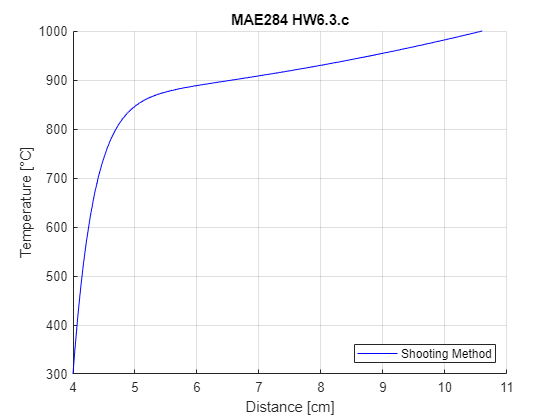

figure()
hold on
plot(x, T(:,1), "-b")

hold off
title("MAE284 HW6.3.c")
xlabel("Distance [cm]")
ylabel("Temperature [°C]")
legend("Shooting Method", "location", "southeast")
grid on

## Problem #4 - Boundary value problem #2

**SETUP FOR PROBLEM**

x0 = 1;
x2 = 2.4;
y0 = 2.2;
yf = 14.2;

% syms y(x)
% Dy = diff(y);
% ode = sqrt(y)*(8-Dy)-diff(y, x, 2) == 0;
% cond1 = y(x0) == 2.2;
% cond2 = y(xf) == 14.2;
% conds = [cond1 cond2];
% solution2(x) = dsolve(ode, conds)

**a) Using shooting method**

**b) Using finite difference approach**

**c) Plot**

**d) Extra Credit (5 pts) Why is the shooting method plotted with a line and the finite difference method plotted just markers?**

ANSWER HERE

## Helper functions